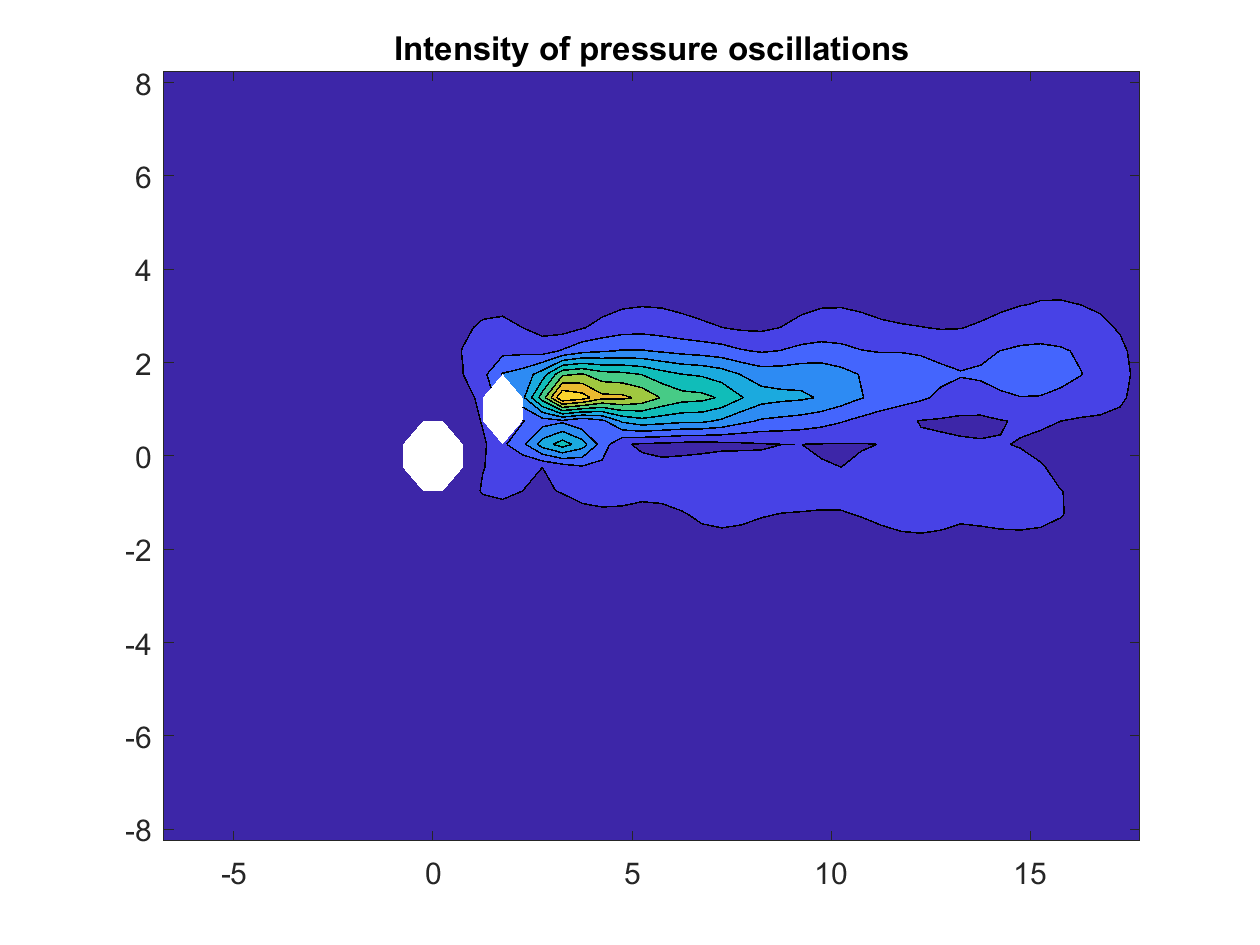

clear; close all

data = load('p_Re_7000_gridx_50_gridy_34.txt');
x = data(:,1);
y = data(:,2);
p = data(:,3:end);

% geometry 
D = 0.1;
W = 25*D;
H = 17*D;
L_rat = 2;
L = L_rat*D;
CX = 5*D+L;
% 2nd cylinder
D_rat = 1;
d = D_rat*D;
alpha = 30;
D_avg = (d+D)/2;
% flow
Re = 7000;
rho = 1000;
mu = 1e-3;
U = Re*mu/(rho*D_avg);
% timestep
St_guess = 0.5;
f_guess = St_guess*U/D_avg;
T_guess = 1/f_guess;
N = 10;
deltaT = T_guess/N;
fs = 1/deltaT;
NN = 100;
fin = deltaT*NN;
% start time
time_st = W/U+0.25;
% output time
t1 = 0:0.2:time_st-0.2;
t2 = time_st:deltaT:time_st+fin;
t = [t1, t2];

p(:, 1:length(t1)) = []; %transient

gridx = 50;
gridy = 34;

X = reshape(x, [gridx, gridy])';
Y = reshape(y, [gridx, gridy])';
[pp, loc, f, AAA,f_dom, A_dom] = get_amp(p,fs);
P = reshape(pp, [gridx,gridy])';

p_max = max(pp,[], 'all');

figure
contourf(X/D,Y/D,P./p_max)
title('Intensity of pressure oscillations')
saveas(gcf, 'powerIntensity.svg')

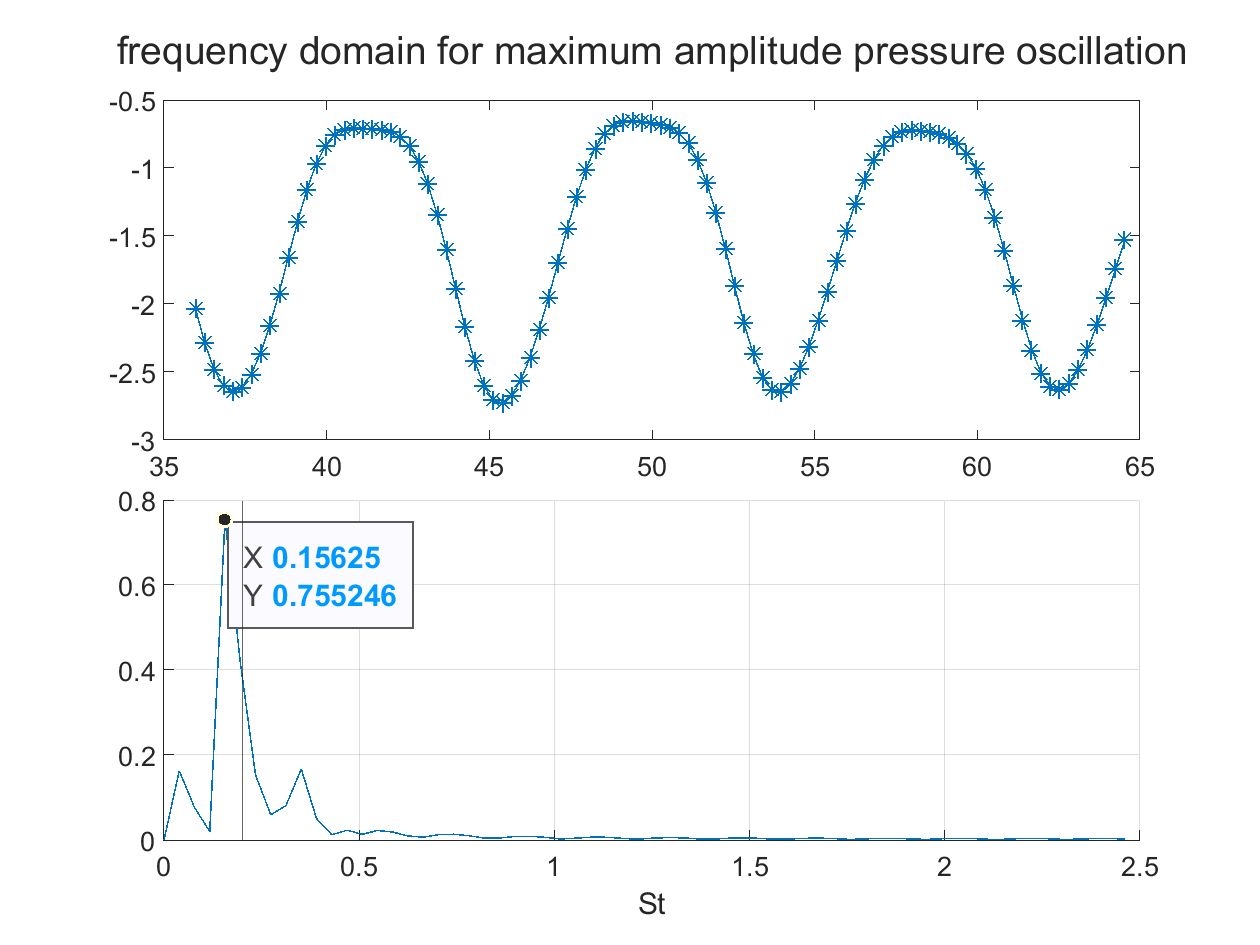


figure
tiledlayout('flow', 'TileSpacing','tight')
nexttile
plot(t2, p(loc, :), Marker="*")
sgtitle('timeseries of pressure oscillations')
nexttile
hold on
plo = plot(f*D_avg/U, AAA);
xline(0.2)
hold off
sgtitle('frequency domain for maximum amplitude pressure oscillation')
grid on
xlabel('St')
datatip(plo, f_dom, A_dom);
saveas(gcf, 'time_and_frq.svg')

function [pp, loc,f,AAA, f_dom, A_dom] = get_amp(p,fs)
    for i=1:size(p,1)
        temp = p(i,:);
        temp = temp - mean(temp);
        L = length(temp);
        n = 2^nextpow2(L);
        A = fft(temp, n);
        A = abs(A(1:n/2))/(n/2);
        f = fs*(0:n/2-1)/n;
        AA(i,:) = A;
        pk(i) = max(A);
    end
    pp = pk;
    [~, loc] = max(pp); 
    AAA = AA(loc,:);
    [A_dom, locc] = max(AAA);
    f_dom = f(locc);
end